# **Hybrid Version(based on loss equality) implementation using MNIST Dataset**

clc; clear; close all;
rng(1);
tic
% LOAD MNIST DATA

function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');
    fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');
    images = fread(fid, inf, 'unsigned char');
    fclose(fid);
    images = reshape(images, numCols*numRows, numImages);
    images = double(images)/255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');
    fread(fid, 1, 'int32', 0, 'ieee-be');
    fread(fid, 1, 'int32', 0, 'ieee-be');
    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);
    labels = double(labels);
end

function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses,length(y));
    for i = 1:length(y)
        Y(y(i)+1,i) = 1;
    end
end

X_train = loadMNISTImages('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\train-images.idx3-ubyte');
y_train = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\train-labels.idx1-ubyte');
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\t10k-images.idx3-ubyte");
y_test  = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\t10k-labels.idx1-ubyte');


Y_train = oneHotEncode(y_train,10);

% NETWORK DIMENSIONS

d0 = 784; d1 = 128; d2 = 64; d3 = 10;

% STANDARD DNN INITIALIZATION using He initialisation(just for a normal
% experiment)

W1 = sqrt(2/d0) * randn(d1,d0); b1 = zeros(d1,1);
W2 = sqrt(2/d1) * randn(d2,d1); b2 = zeros(d2,1);
W3 = sqrt(2/d2) * randn(d3,d2); b3 = zeros(d3,1);

% SVD INITIALIZATION

r1 = min(d1,d0); r2 = min(d2,d1); r3 = min(d3,d2);

[U1,~] = qr(randn(d1,r1),0); [V1,~] = qr(randn(d0,r1),0); alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0); [V2,~] = qr(randn(d1,r2),0); alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0); [V3,~] = qr(randn(d2,r3),0); alpha3 = randn(r3,1);

% TRAINING SETTINGS


epochs = 50;
batch_size = 128;
lr = 1e-3;
tolerance = 3e-1;
switched = false;
switch_epoch = -1;

N = size(X_train,2);
num_batches = floor(N/batch_size);

loss_std_hist = zeros(epochs,1);
loss_svd_hist = zeros(epochs,1);

% TRAINING LOOP

for epoch = 1:epochs
    
    perm = randperm(N);
    epoch_loss_std = 0;
    epoch_loss_svd = 0;

    for b = 1:num_batches
        
        idx = perm((b-1)*batch_size+1:b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        %%  STANDARD FORWARD 
        Z1 = W1*X + b1; A1 = max(0,Z1);
        Z2 = W2*A1 + b2; A2 = max(0,Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3,[],1);
        expZ = exp(Z3);
        Yhat_std = expZ ./ sum(expZ,1);

        loss_std = -sum(sum(Y.*log(Yhat_std+1e-8)))/m;
        epoch_loss_std = epoch_loss_std + loss_std;

        %%  SVD FORWARD 
        if ~switched
            
            s1 = exp(alpha1); S1 = diag(sqrt(s1));
            s2 = exp(alpha2); S2 = diag(sqrt(s2));
            s3 = exp(alpha3); S3 = diag(sqrt(s3));

            H1 = S1*(V1'*X); Z1s = U1*S1*H1; A1s = max(0,Z1s);
            H2 = S2*(V2'*A1s); Z2s = U2*S2*H2; A2s = max(0,Z2s);
            H3 = S3*(V3'*A2s); Z3s = U3*S3*H3;

            Z3s = Z3s - max(Z3s,[],1);
            expZs = exp(Z3s);
            Yhat_svd = expZs ./ sum(expZs,1);

            loss_svd = -sum(sum(Y.*log(Yhat_svd+1e-8)))/m;
            epoch_loss_svd = epoch_loss_svd + loss_svd;
        end

        %% STANDARD BACKPROP
        dZ3 = Yhat_std - Y;
        dW3 = (1/m)*dZ3*A2';
        db3 = (1/m)*sum(dZ3,2);

        dA2 = W3'*dZ3;
        dZ2 = dA2.*(Z2>0);
        dW2 = (1/m)*dZ2*A1';
        db2 = (1/m)*sum(dZ2,2);

        dA1 = W2'*dZ2;
        dZ1 = dA1.*(Z1>0);
        dW1 = (1/m)*dZ1*X';
        db1 = (1/m)*sum(dZ1,2);

        W3 = W3 - lr*dW3; b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2; b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1; b1 = b1 - lr*db1;

        %% SVD BACKPROP 
        if ~switched
            
            dZ3s = Yhat_svd - Y;
            dU3 = (dZ3s*(S3*H3)')/m;
            dH3 = (U3*S3)'*dZ3s;
            dV3 = (A2s*(dH3'*S3))/m;
            ds3 = diag((U3'*dZ3s)*H3')/m;

            dA2s = V3*(S3*dH3); dZ2s = dA2s.*(Z2s>0);
            dU2 = (dZ2s*(S2*H2)')/m;
            dH2 = (U2*S2)'*dZ2s;
            dV2 = (A1s*(dH2'*S2))/m;
            ds2 = diag((U2'*dZ2s)*H2')/m;

            dA1s = V2*(S2*dH2); dZ1s = dA1s.*(Z1s>0);
            dU1 = (dZ1s*(S1*H1)')/m;
            dH1 = (U1*S1)'*dZ1s;
            dV1 = (X*(dH1'*S1))/m;
            ds1 = diag((U1'*dZ1s)*H1')/m;

            alpha1 = alpha1 - lr*(ds1.*s1);
            alpha2 = alpha2 - lr*(ds2.*s2);
            alpha3 = alpha3 - lr*(ds3.*s3);

            U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
            U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
            U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;
        end
    end

    loss_std_hist(epoch) = epoch_loss_std/num_batches;
    if ~switched
        loss_svd_hist(epoch) = epoch_loss_svd/num_batches;
    end

    fprintf('Epoch %d | STD Loss %.4f', epoch, loss_std_hist(epoch));
    if ~switched
        fprintf(' | SVD Loss %.4f', loss_svd_hist(epoch));
    end
    fprintf('\n');

    %% SWITCH CONDITION
    if ~switched
        if abs(loss_std_hist(epoch) - loss_svd_hist(epoch)) < tolerance
            
            fprintf('\n SWITCHING TO STANDARD USING SVD WEIGHTS \n');

            W1 = U1*diag(exp(alpha1))*V1';
            W2 = U2*diag(exp(alpha2))*V2';
            W3 = U3*diag(exp(alpha3))*V3';

            switched = true;
            switch_epoch = epoch;
        end
    end
end

Epoch 1 | STD Loss 2.2129

 | SVD Loss 1.2075

Epoch 2 | STD Loss 1.9037

 | SVD Loss 0.5856

Epoch 3 | STD Loss 1.5987

 | SVD Loss 0.4552

Epoch 4 | STD Loss 1.3135

 | SVD Loss 0.3918

Epoch 5 | STD Loss 1.0846

 | SVD Loss 0.3507

Epoch 6 | STD Loss 0.9168

 | SVD Loss 0.3226

Epoch 7 | STD Loss 0.7965

 | SVD Loss 0.2997

Epoch 8 | STD Loss 0.7093

 | SVD Loss 0.2813

Epoch 9 | STD Loss 0.6451

 | SVD Loss 0.2667

Epoch 10 | STD Loss 0.5961

 | SVD Loss 0.2533

Epoch 11 | STD Loss 0.5580

 | SVD Loss 0.2414

Epoch 12 | STD Loss 0.5274

 | SVD Loss 0.2313


 SWITCHING TO STANDARD USING SVD WEIGHTS 


Epoch 13 | STD Loss 0.2199

Epoch 14 | STD Loss 0.2175

Epoch 15 | STD Loss 0.2157

Epoch 16 | STD Loss 0.2138

Epoch 17 | STD Loss 0.2122

Epoch 18 | STD Loss 0.2105

Epoch 19 | STD Loss 0.2090

Epoch 20 | STD Loss 0.2074

Epoch 21 | STD Loss 0.2060

Epoch 22 | STD Loss 0.2043

Epoch 23 | STD Loss 0.2030

Epoch 24 | STD Loss 0.2017

Epoch 25 | STD Loss 0.2003

Epoch 26 | STD Loss 0.1991

Epoch 27 | STD Loss 0.1979

Epoch 28 | STD Loss 0.1963

Epoch 29 | STD Loss 0.1952

Epoch 30 | STD Loss 0.1941

Epoch 31 | STD Loss 0.1928

Epoch 32 | STD Loss 0.1917

Epoch 33 | STD Loss 0.1904

Epoch 34 | STD Loss 0.1896

Epoch 35 | STD Loss 0.1881

Epoch 36 | STD Loss 0.1875

Epoch 37 | STD Loss 0.1864

Epoch 38 | STD Loss 0.1853

Epoch 39 | STD Loss 0.1844

Epoch 40 | STD Loss 0.1833

Epoch 41 | STD Loss 0.1822

Epoch 42 | STD Loss 0.1814

Epoch 43 | STD Loss 0.1804

Epoch 44 | STD Loss 0.1790

Epoch 45 | STD Loss 0.1784

Epoch 46 | STD Loss 0.1776

Epoch 47 | STD Loss 0.1768

Epoch 48 | STD Loss 0.1758

Epoch 49 | STD Loss 0.1752

Epoch 50 | STD Loss 0.1740

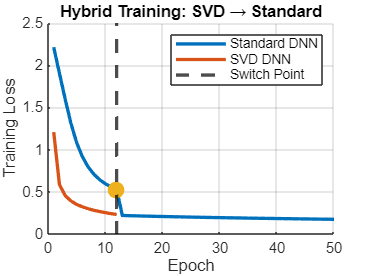


% LOSS CURVE

figure;
hold on;
plot(loss_std_hist,'LineWidth',2);

if switch_epoch ~= -1
    plot(1:switch_epoch, loss_svd_hist(1:switch_epoch),'LineWidth',2);
    xline(switch_epoch,'k--','LineWidth',2);
    scatter(switch_epoch, loss_std_hist(switch_epoch),100,'filled');
end

xlabel('Epoch');
ylabel('Training Loss');
title('Hybrid Training: SVD → Standard');
legend('Standard DNN','SVD DNN','Switch Point');
grid on;
hold off;


% TEST EVALUATION

Z1 = W1*X_test + b1; A1 = max(0,Z1);
Z2 = W2*A1 + b2; A2 = max(0,Z2);
Z3 = W3*A2 + b3;

[~,pred] = max(Z3,[],1);
pred = pred - 1;

accuracy = mean(pred'==y_test)*100;
fprintf('\nFinal Test Accuracy: %.2f%%\n', accuracy);


Final Test Accuracy: 94.27%


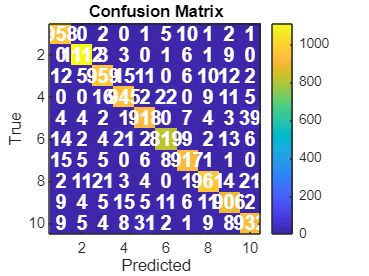


conf_mat = zeros(10,10);
for i = 1:length(y_test)
    conf_mat(y_test(i)+1, pred(i)+1) = ...
        conf_mat(y_test(i)+1, pred(i)+1) + 1;
end

figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted');
ylabel('True');
title('Confusion Matrix');
axis square;

for i = 1:size(conf_mat,1)
    for j = 1:size(conf_mat,2)
        text(j, i, num2str(conf_mat(i,j)), ...
            'HorizontalAlignment','center', ...
            'Color','white', ...
            'FontSize',12, ...
            'FontWeight','bold');
    end
end

toc

Elapsed time is 138.614576 seconds.


# **Hybrid Version(based on loss equality) implementation using Fashion-MNIST Dataset**

clearvars;
rng(1);
tic
% LOAD MNIST DATA



X_train = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\train-images-idx3-ubyte");
y_train = loadMNISTLabels("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\train-labels-idx1-ubyte");
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\t10k-images-idx3-ubyte");
y_test  = loadMNISTLabels("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\t10k-labels-idx1-ubyte");


Y_train = oneHotEncode(y_train,10);

% NETWORK DIMENSIONS

d0 = 784; d1 = 128; d2 = 64; d3 = 10;

% STANDARD DNN INITIALIZATION using He initialisation(just for a normal
% experiment)

W1 = sqrt(2/d0) * randn(d1,d0); b1 = zeros(d1,1);
W2 = sqrt(2/d1) * randn(d2,d1); b2 = zeros(d2,1);
W3 = sqrt(2/d2) * randn(d3,d2); b3 = zeros(d3,1);

% SVD INITIALIZATION

r1 = min(d1,d0); r2 = min(d2,d1); r3 = min(d3,d2);

[U1,~] = qr(randn(d1,r1),0); [V1,~] = qr(randn(d0,r1),0); alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0); [V2,~] = qr(randn(d1,r2),0); alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0); [V3,~] = qr(randn(d2,r3),0); alpha3 = randn(r3,1);

% TRAINING SETTINGS


epochs = 50;
batch_size = 128;
lr = 1e-3;
tolerance = 3e-1;
switched = false;
switch_epoch = -1;

N = size(X_train,2);
num_batches = floor(N/batch_size);

loss_std_hist = zeros(epochs,1);
loss_svd_hist = zeros(epochs,1);

% TRAINING LOOP

for epoch = 1:epochs
    
    perm = randperm(N);
    epoch_loss_std = 0;
    epoch_loss_svd = 0;

    for b = 1:num_batches
        
        idx = perm((b-1)*batch_size+1:b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        %%  STANDARD FORWARD 
        Z1 = W1*X + b1; A1 = max(0,Z1);
        Z2 = W2*A1 + b2; A2 = max(0,Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3,[],1);
        expZ = exp(Z3);
        Yhat_std = expZ ./ sum(expZ,1);

        loss_std = -sum(sum(Y.*log(Yhat_std+1e-8)))/m;
        epoch_loss_std = epoch_loss_std + loss_std;

        %%  SVD FORWARD 
        if ~switched
            
            s1 = exp(alpha1); S1 = diag(sqrt(s1));
            s2 = exp(alpha2); S2 = diag(sqrt(s2));
            s3 = exp(alpha3); S3 = diag(sqrt(s3));

            H1 = S1*(V1'*X); Z1s = U1*S1*H1; A1s = max(0,Z1s);
            H2 = S2*(V2'*A1s); Z2s = U2*S2*H2; A2s = max(0,Z2s);
            H3 = S3*(V3'*A2s); Z3s = U3*S3*H3;

            Z3s = Z3s - max(Z3s,[],1);
            expZs = exp(Z3s);
            Yhat_svd = expZs ./ sum(expZs,1);

            loss_svd = -sum(sum(Y.*log(Yhat_svd+1e-8)))/m;
            epoch_loss_svd = epoch_loss_svd + loss_svd;
        end

        %% STANDARD BACKPROP
        dZ3 = Yhat_std - Y;
        dW3 = (1/m)*dZ3*A2';
        db3 = (1/m)*sum(dZ3,2);

        dA2 = W3'*dZ3;
        dZ2 = dA2.*(Z2>0);
        dW2 = (1/m)*dZ2*A1';
        db2 = (1/m)*sum(dZ2,2);

        dA1 = W2'*dZ2;
        dZ1 = dA1.*(Z1>0);
        dW1 = (1/m)*dZ1*X';
        db1 = (1/m)*sum(dZ1,2);

        W3 = W3 - lr*dW3; b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2; b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1; b1 = b1 - lr*db1;

        %% SVD BACKPROP 
        if ~switched
            
            dZ3s = Yhat_svd - Y;
            dU3 = (dZ3s*(S3*H3)')/m;
            dH3 = (U3*S3)'*dZ3s;
            dV3 = (A2s*(dH3'*S3))/m;
            ds3 = diag((U3'*dZ3s)*H3')/m;

            dA2s = V3*(S3*dH3); dZ2s = dA2s.*(Z2s>0);
            dU2 = (dZ2s*(S2*H2)')/m;
            dH2 = (U2*S2)'*dZ2s;
            dV2 = (A1s*(dH2'*S2))/m;
            ds2 = diag((U2'*dZ2s)*H2')/m;

            dA1s = V2*(S2*dH2); dZ1s = dA1s.*(Z1s>0);
            dU1 = (dZ1s*(S1*H1)')/m;
            dH1 = (U1*S1)'*dZ1s;
            dV1 = (X*(dH1'*S1))/m;
            ds1 = diag((U1'*dZ1s)*H1')/m;

            alpha1 = alpha1 - lr*(ds1.*s1);
            alpha2 = alpha2 - lr*(ds2.*s2);
            alpha3 = alpha3 - lr*(ds3.*s3);

            U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
            U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
            U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;
        end
    end

    loss_std_hist(epoch) = epoch_loss_std/num_batches;
    if ~switched
        loss_svd_hist(epoch) = epoch_loss_svd/num_batches;
    end

    fprintf('Epoch %d | STD Loss %.4f', epoch, loss_std_hist(epoch));
    if ~switched
        fprintf(' | SVD Loss %.4f', loss_svd_hist(epoch));
    end
    fprintf('\n');

    %% SWITCH CONDITION
    if ~switched
        if abs(loss_std_hist(epoch) - loss_svd_hist(epoch)) < tolerance
            
            fprintf('\n SWITCHING TO STANDARD USING SVD WEIGHTS \n');

            W1 = U1*diag(exp(alpha1))*V1';
            W2 = U2*diag(exp(alpha2))*V2';
            W3 = U3*diag(exp(alpha3))*V3';

            switched = true;
            switch_epoch = epoch;
        end
    end
end

Epoch 1 | STD Loss 1.9718

 | SVD Loss 1.1536

Epoch 2 | STD Loss 1.4342

 | SVD Loss 0.6931

Epoch 3 | STD Loss 1.1509

 | SVD Loss 0.6076

Epoch 4 | STD Loss 0.9963

 | SVD Loss 0.5633

Epoch 5 | STD Loss 0.9028

 | SVD Loss 0.5321

Epoch 6 | STD Loss 0.8398

 | SVD Loss 0.5079

Epoch 7 | STD Loss 0.7932

 | SVD Loss 0.4906

Epoch 8 | STD Loss 0.7570

 | SVD Loss 0.4756


 SWITCHING TO STANDARD USING SVD WEIGHTS 


Epoch 9 | STD Loss 0.4545

Epoch 10 | STD Loss 0.4509

Epoch 11 | STD Loss 0.4486

Epoch 12 | STD Loss 0.4462

Epoch 13 | STD Loss 0.4441

Epoch 14 | STD Loss 0.4425

Epoch 15 | STD Loss 0.4406

Epoch 16 | STD Loss 0.4387

Epoch 17 | STD Loss 0.4373

Epoch 18 | STD Loss 0.4353

Epoch 19 | STD Loss 0.4337

Epoch 20 | STD Loss 0.4323

Epoch 21 | STD Loss 0.4308

Epoch 22 | STD Loss 0.4294

Epoch 23 | STD Loss 0.4280

Epoch 24 | STD Loss 0.4265

Epoch 25 | STD Loss 0.4250

Epoch 26 | STD Loss 0.4236

Epoch 27 | STD Loss 0.4225

Epoch 28 | STD Loss 0.4214

Epoch 29 | STD Loss 0.4200

Epoch 30 | STD Loss 0.4190

Epoch 31 | STD Loss 0.4177

Epoch 32 | STD Loss 0.4165

Epoch 33 | STD Loss 0.4153

Epoch 34 | STD Loss 0.4142

Epoch 35 | STD Loss 0.4129

Epoch 36 | STD Loss 0.4121

Epoch 37 | STD Loss 0.4110

Epoch 38 | STD Loss 0.4101

Epoch 39 | STD Loss 0.4094

Epoch 40 | STD Loss 0.4082

Epoch 41 | STD Loss 0.4068

Epoch 42 | STD Loss 0.4062

Epoch 43 | STD Loss 0.4051

Epoch 44 | STD Loss 0.4041

Epoch 45 | STD Loss 0.4029

Epoch 46 | STD Loss 0.4021

Epoch 47 | STD Loss 0.4013

Epoch 48 | STD Loss 0.4002

Epoch 49 | STD Loss 0.3996

Epoch 50 | STD Loss 0.3987

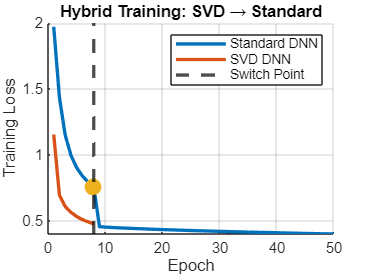


% LOSS CURVE

figure;
hold on;
plot(loss_std_hist,'LineWidth',2);

if switch_epoch ~= -1
    plot(1:switch_epoch, loss_svd_hist(1:switch_epoch),'LineWidth',2);
    xline(switch_epoch,'k--','LineWidth',2);
    scatter(switch_epoch, loss_std_hist(switch_epoch),100,'filled');
end

xlabel('Epoch');
ylabel('Training Loss');
title('Hybrid Training: SVD → Standard');
legend('Standard DNN','SVD DNN','Switch Point');
grid on;
hold off;


% TEST EVALUATION

Z1 = W1*X_test + b1; A1 = max(0,Z1);
Z2 = W2*A1 + b2; A2 = max(0,Z2);
Z3 = W3*A2 + b3;

[~,pred] = max(Z3,[],1);
pred = pred - 1;

accuracy = mean(pred'==y_test)*100;
fprintf('\nFinal Test Accuracy: %.2f%%\n', accuracy);


Final Test Accuracy: 84.12%


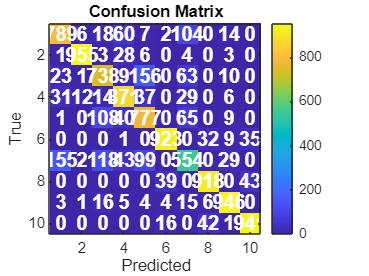


conf_mat = zeros(10,10);
for i = 1:length(y_test)
    conf_mat(y_test(i)+1, pred(i)+1) = ...
        conf_mat(y_test(i)+1, pred(i)+1) + 1;
end

figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted');
ylabel('True');
title('Confusion Matrix');
axis square;

for i = 1:size(conf_mat,1)
    for j = 1:size(conf_mat,2)
        text(j, i, num2str(conf_mat(i,j)), ...
            'HorizontalAlignment','center', ...
            'Color','white', ...
            'FontSize',12, ...
            'FontWeight','bold');
    end
end

toc

Elapsed time is 79.151490 seconds.
